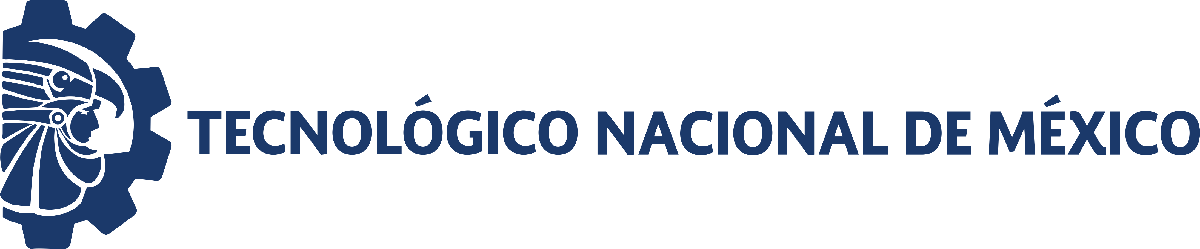                                 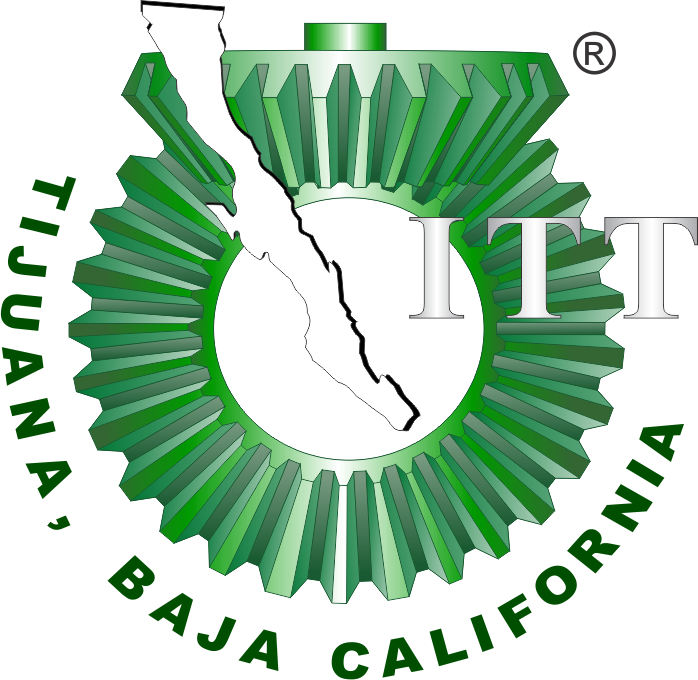

# Práctica dos: Sistema pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[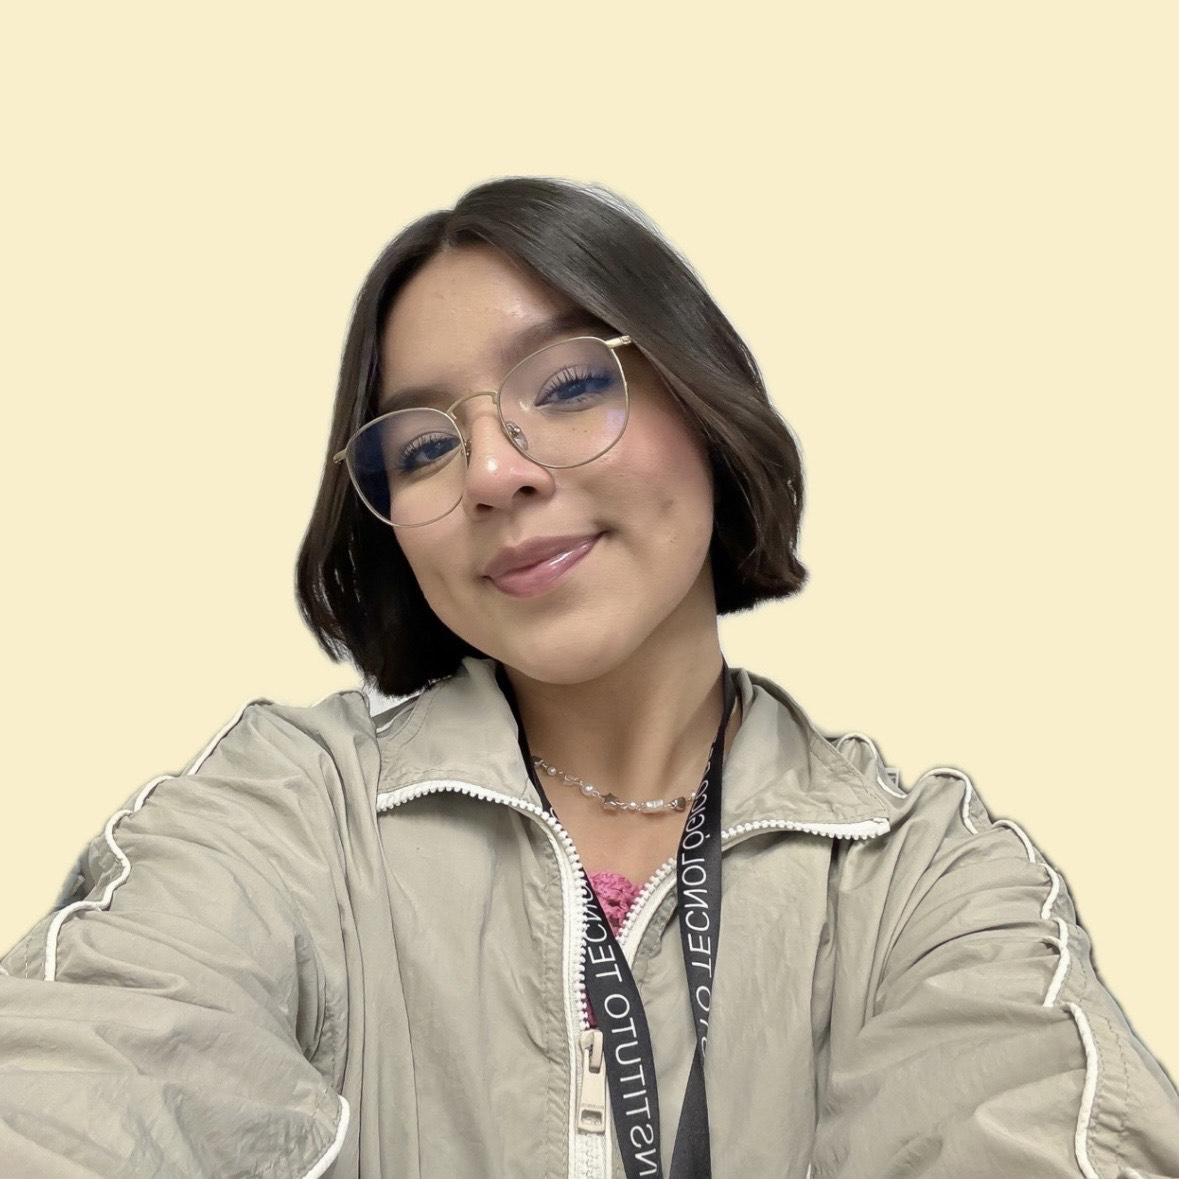]

Nombre del alumno: **Leslie Avelladith Marin Paredes **

Número de control: **20212506**

Correo institucional: **l20212506@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '30'; 
file = 'Sano';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15';
parameters.MaxStep = '1E-3';
Controlador = 'PID';


## **Rendimiento del controlador**

kP: 15.8954

kI: 452.1208

kD: 0.042897

Settling time: 0.0994

Overshoot: 9.37%

Peak: 1.09 

## Respiración normal

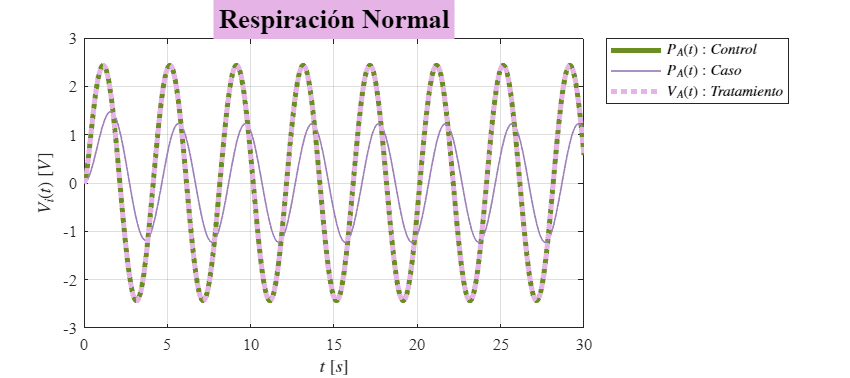

Signal = 'Respiración Normal';
set_param('Sano/Pao(t)','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.PAx,x1.PAy,x1.PAz,Signal) %to workspace buscar en el library browser del sysp0 
title('Respiración Normal','FontSize',16,'BackgroundColor',[0.9,0.7,0.9])

## Respiración elevada [taquipnea]

Signal = 'Respiración elevada [taquipnea]';
set_param('Sano/Pao(t)','sw','0');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.PAx,x2.PAy,x2.PAz,Signal) %to workspace buscar en el library browser del sysp0  
[t,s] = title('Respiración elevada','[taquipnea]','BackgroundColor',[0.9,0.7,0.9])

t =   Text (Respiración elevada) with properties:

                 String: 'Respiración elevada'
               FontSize: 11
             FontWeight: 'bold'
               FontName: 'Times New Roman'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [7.5000 3.5719 0]
                  Units: 'data'

  Show all properties


s =   Text ([taquipnea]) with properties:

                 String: '[taquipnea]'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Times New Roman'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [7.5000 3.0594 0]
                  Units: 'data'

  Show all properties


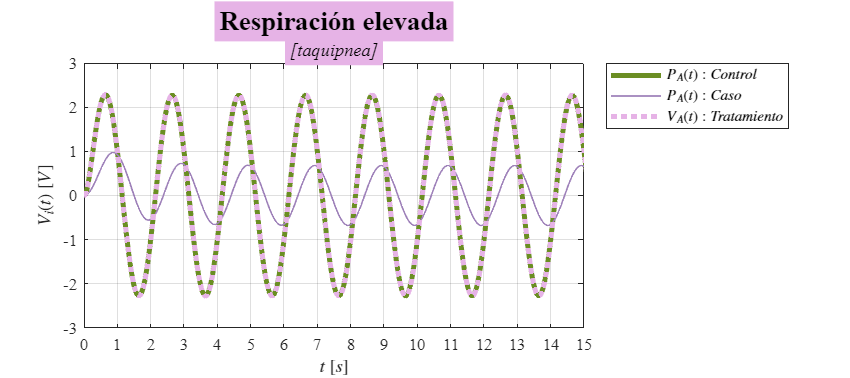

t.FontSize = 16;
s.FontAngle = 'italic';

## **Función: Respuesta a las señales**

function plotsignals(t,PAx,PAy,PAz,Signal)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(10, 'points')
    am = [107/255, 142/255, 35/255];
    rf = [158/255,129/255,185/255];
    na = [0.9,0.7,0.9];
    hold on; grid on; box on

    plot(t,PAx,'LineWidth',3,'Color',am)
    plot(t,PAy,'LineWidth',1,'Color',rf)
    plot(t,PAz,':','LineWidth',3,'Color',na)

    xlabel('$t$ $[s]$','Interpreter','Latex')
    ylabel('$V_{i}(t)$ $[V]$','Interpreter','Latex')

    L = legend('$P_{A}(t): Control$','$P_{A}(t): Caso$','$V_{A}(t): Tratamiento$');
    set(L,'Interpreter','Latex','Location','Bestoutside','Box','On')

    if Signal == "Respiración Normal"
        xlim([0,30]); xticks(0:5:30)  %dominio
        ylim([-3,3]); yticks(-3:1:3)  %rango
    elseif Signal == "Respiración elevada [taquipnea]"
        xlim([0,15]); xticks(0:1:15)
        ylim([-3,3]); yticks(-3:1:3)
    end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end